# Stability

clear all

## Inputs

Tx = 1;
Ty = 1;
alpha = 0.1;
Re = 30;

dpdx = -12;
ml_array = 5:2:19;
C_err = nan(size(ml_array));
u_err_max = nan(size(ml_array));
u_err_mean = nan(size(ml_array));

for i=1:size(ml_array,2)
m = ml_array(i);
l = m;
[u,v,C] = Main(Re,alpha,Tx,Ty,m,l);
C_err(i) = (C(end)-dpdx)/dpdx*100;
ud_FD = u_FD(m);
u_err = abs((u(2:end-1,end)-ud_FD(2:end-1))./ud_FD(2:end-1))*100;
u_err_max(i) = max(u_err,[],1);
u_err_mean(i) = mean(u_err,1);
end

## Plots

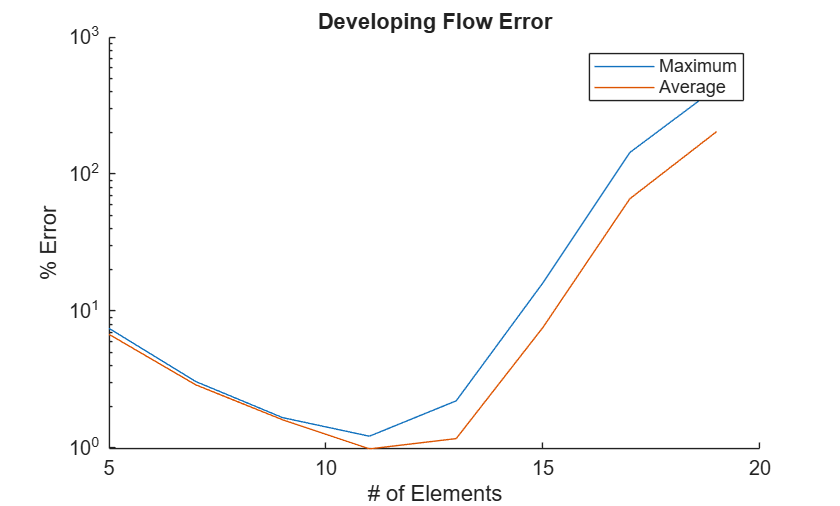

figure(Theme="light");
hold on
plot(ml_array,u_err_max,'DisplayName',"Maximum")
plot(ml_array,u_err_mean,'DisplayName',"Average")
set(gca, 'YScale', 'log')
ylabel("% Error")
xlabel("# of Elements")
legend()
title("Developing Flow Error")
hold off

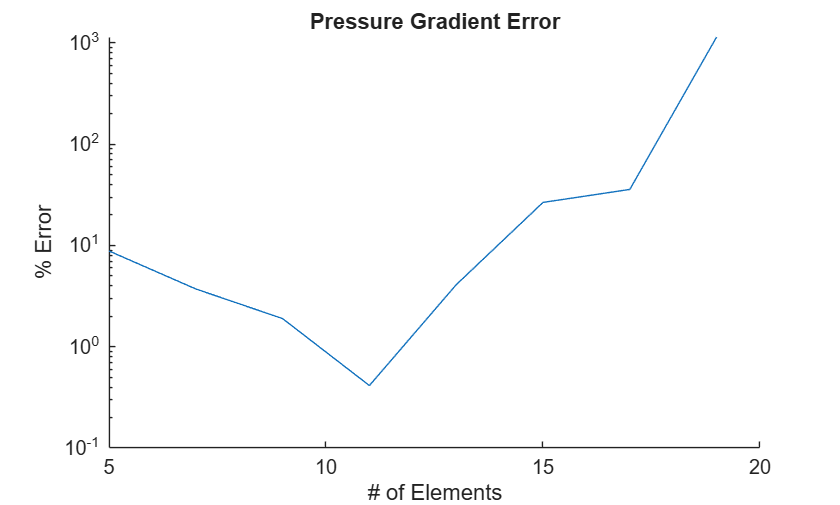

figure(Theme="light");
hold on
plot(ml_array,abs(C_err))
ylabel("% Error")
title("Pressure Gradient Error")
xlabel("# of Elements")
set(gca, 'YScale', 'log')
hold off